clc; clear all; close all;
[file, path] = uigetfile('*.wav')

file = 'rawSpeech.wav'

path = 'C:\Users\Mouse Bro\Desktop\Final_demo\recording\'

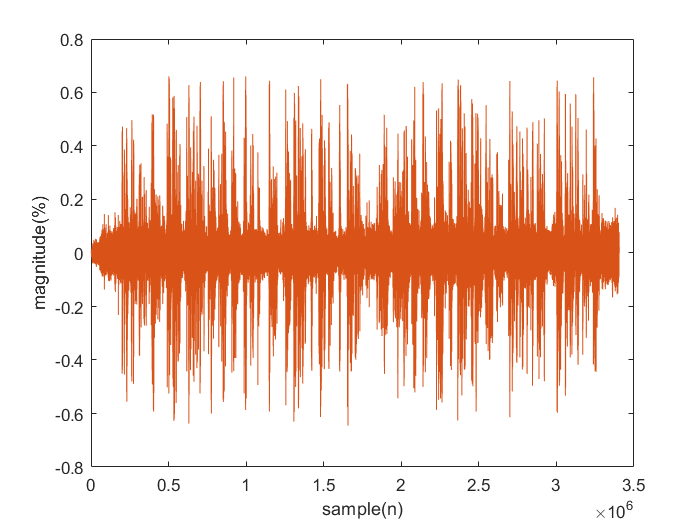

[y, Fs] = audioread(fullfile(path,file));
plot(y)
xlabel('sample(n)');
ylabel('magnitude(%)');

n = length(y); F = 0:(n-1)*Fs/n;
yf = fft(y,n);
F0 = (-n/2:n/2-1).*(Fs/n);
yf0 = fftshift(yf);
yf0 = yf0 / max(yf0); % normalize
center = abs(F0(1,find(yf0 == max(yf0))))

center = 497.3825

figure
semilogx(F0, abs(yf0))
axis([0 20000 0 1])

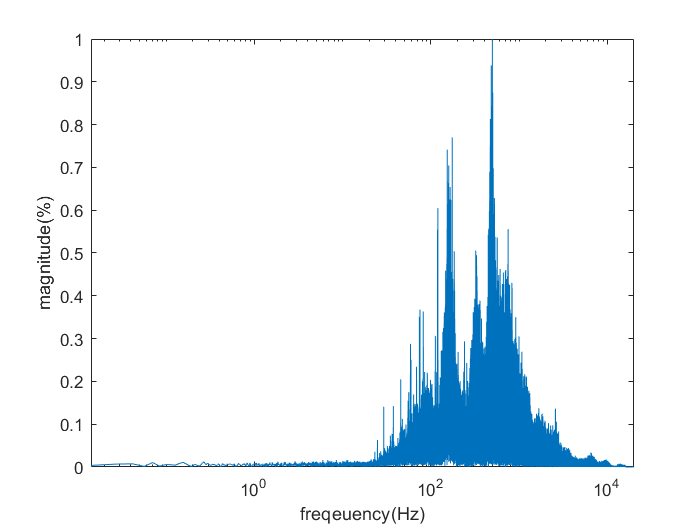

xlabel('freqeuency(Hz)');
ylabel('magnitude(%)');

## filter

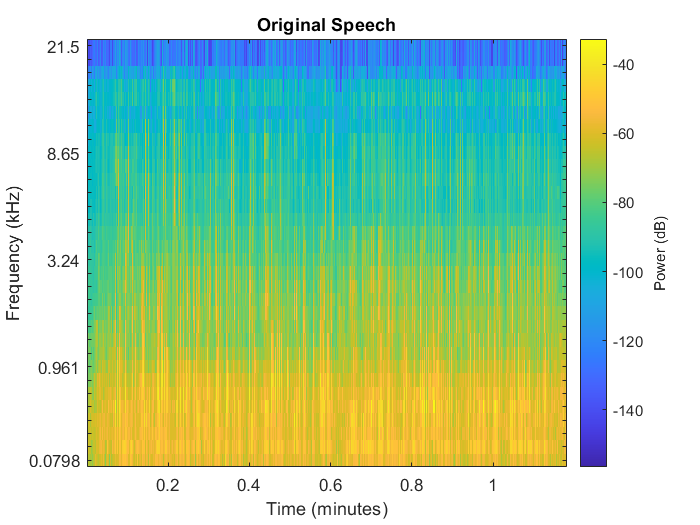

h  = fdesign.bandpass('N,F3dB1,F3dB2', 20, center - 300, center + 700, 16000);
filter2 = design(h, 'butter');
melSpectrogram(y,Fs)
title('Original Speech');

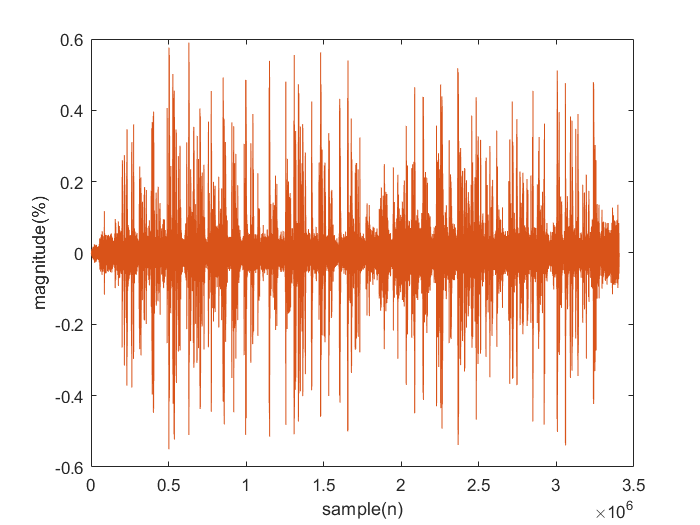


x = filter(filter2,y);
figure
plot(x);
xlabel('sample(n)');
ylabel('magnitude(%)');

xf = fft(x,n);
xf0 = fftshift(xf);
xf0 = xf0/max(xf0);
figure
semilogx(F0, abs(xf0))
axis([0 20000 0 1])

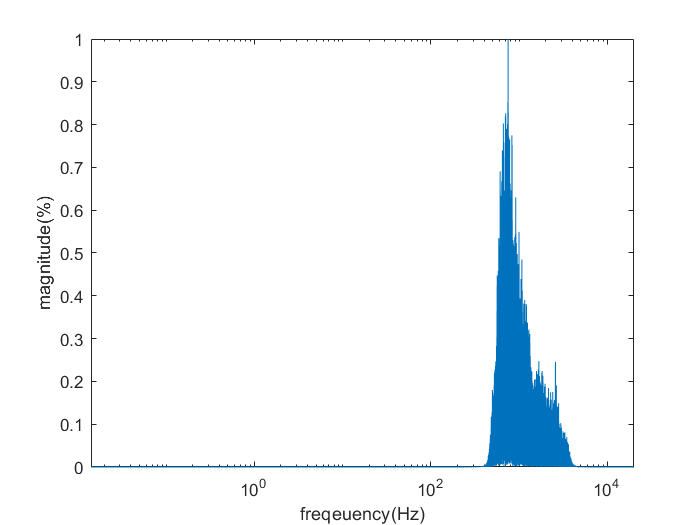

xlabel('freqeuency(Hz)');
ylabel('magnitude(%)');

## wavedec

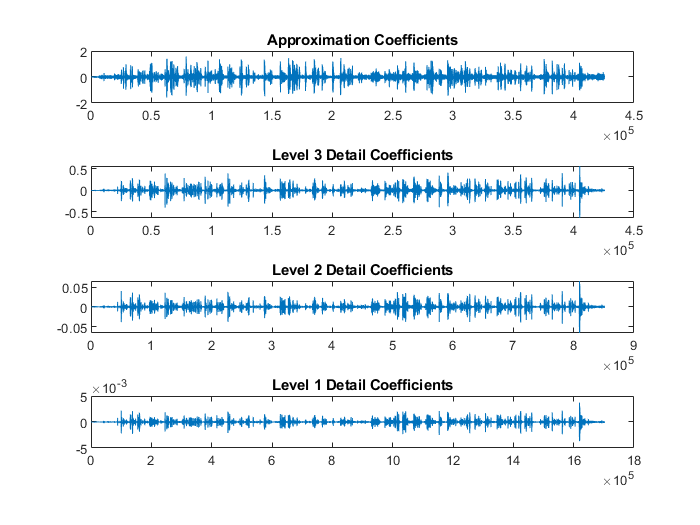



[c,l] = wavedec(x(:,1), 3, 'db4');
b = wthresh(c, 's', 0.1);
r = waverec(b,l,'db4');

[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);
approx = appcoef(c,l,'db4');
subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

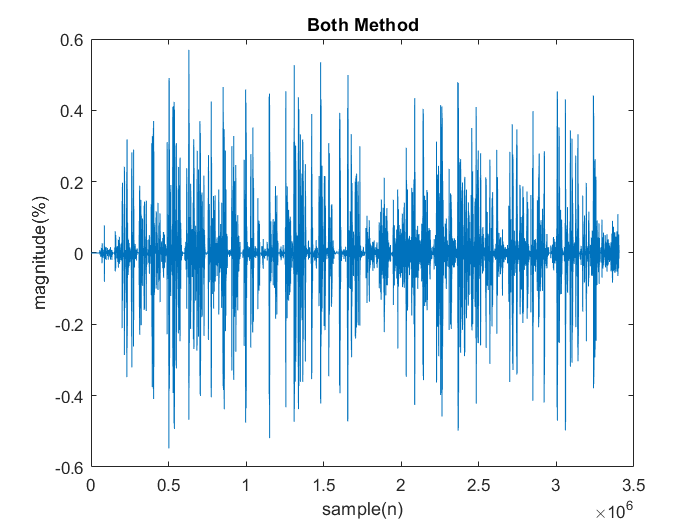


figure();
plot(r);
xlabel('sample(n)');
ylabel('magnitude(%)');
title('Both Method')

fn1 = sprintf('./result/%s-filtered.wav', file);
fn2 = sprintf('./result/%s-wavdeced.wav', file);
audiowrite(fn1,x,Fs)
%audiowrite('rawSpeech-wave-decomposition-and-threshold.wav',z,Fs);
audiowrite(fn2,r,Fs)


